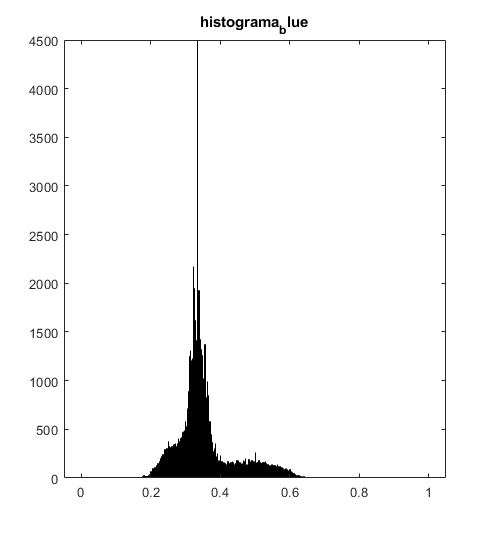

ans = 0

ans = 10


imPrueba = imread('01.jpg');

imshow(imPrueba)
rTest = imPrueba(:,:,1);
gTest = imPrueba(:,:,2);
bTest = imPrueba(:,:,3);
ITest = double(rTest)+double(gTest)+double(bTest);
rTestn = double(rTest)./ITest;
gTestn = double(gTest)./ITest;
bTestn = double(bTest)./ITest;
rgbTestNormalizada = cat(3,rTestn,gTestn,bTestn);
imshow(rgbTestNormalizada), title('normalitzacio naive');
auxTest = 0:0.001:1;
%%Normalizacion
rgbTestNormalizada = histeq(rgbTestNormalizada);
imshow(rgbTestNormalizada), title('Histograma Equalizado')


%aux = 0:256
histogram(rgbTestNormalizada(:,:,1),auxTest), title('histograma_red');
histogram(rgbTestNormalizada(:,:,3),auxTest), title('histograma_blue');

%Algoritmo
length_blue = zeros(1,30);
length_red = zeros(1,30);
for i = 28:28
    if i < 10
        im = imread(strcat('0', int2str(i) ,'.jpg'));
    else
        im = imread(strcat( int2str(i) ,'.jpg'));
    end
    imshow(im)
    r = im(:,:,1);
    g = im(:,:,2);
    b = im(:,:,3);
    I = double(r)+double(g)+double(b);
    rn = double(r)./I;
    gn = double(g)./I;
    bn = double(b)./I;
    rgbNormalizada = cat(3,rn,gn,bn);
    imshow(rgbNormalizada), title('normalitzacio naive')
    %%Normalizacion
    rgbNormalizada = histeq(rgbNormalizada);
    imshow(rgbNormalizada), title('Histograma Equalizado')
    aux = 0:0.001:1;
    %aux = 0:256
    histogram(rgbNormalizada(:,:,1),aux), title('histograma_red');
    histogram(rgbNormalizada(:,:,3),aux), title('histograma_blue');
    %length_red(i) =  length(rn(rn>0.7));
    %length_blue(i)= length(bn(bn>0.7));
end

